# Semantic Segmentation Using Deep Learning

## Setup

This example creates the Deeplab v3+ network with weights initialized from a pre-trained Resnet-18 network. ResNet-18 is an efficient network that is well suited for applications with limited processing resources. Other pretrained networks such as MobileNet v2 or ResNet-50 can also be used depending on application requirements.

A CUDA-capable NVIDIA™ GPU with compute capability 3.0 or higher is highly recommended for running this example. Use of a GPU requires Parallel Computing Toolbox™.

% outputFolder = pwd;
currentFolder = 'C:\Users\vvd5140\Documents\MATLAB\Examples\R2019a\deeplearning_shared\SemanticSegOfMultispectralImagesUsingDeepLearningExample';

## Load CamVid Images

Use `imageDatastore` to load CamVid images. The  `imageDatastore` enables you to efficiently load a large collection of images on disk.

imgDir = fullfile(currentFolder,'images');
imds = imageDatastore(imgDir,'FileExtensions','.jpg','IncludeSubfolders',true);

% sort the files in natural order, i.e., 1,2,3,...
imds.Files = natsortfiles(imds.Files);
numFrames = numel(imds.Files);

imds.ReadFcn = @customReadDatastoreImage;

Display one of the images.

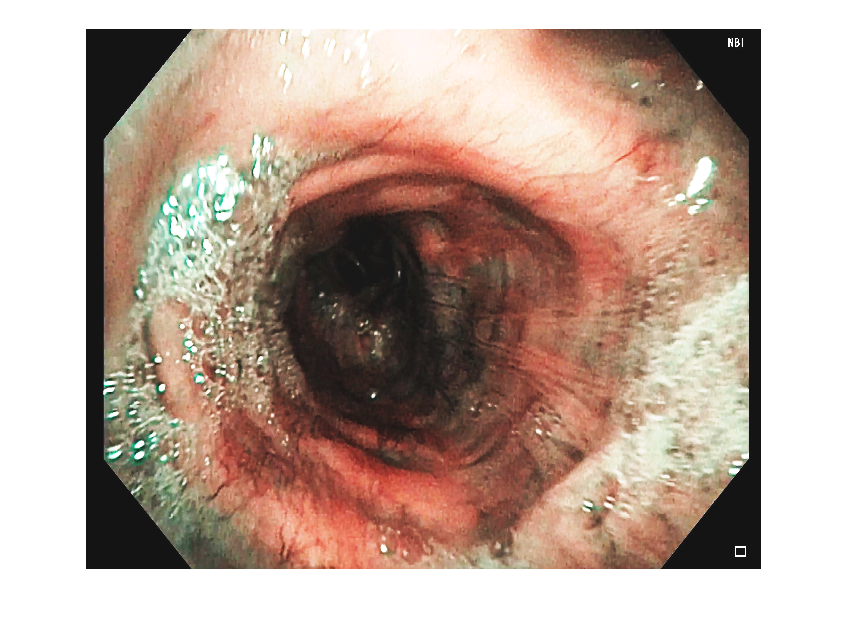

randNum = randi(numFrames);
I = readimage(imds,randNum);
I = histeq(I);
imshow(I)

## Load Pixel-Labeled Images

Use `pixelLabelDatastore` to load pixel label image data. A `pixelLabelDatastore` encapsulates the pixel label data and the label ID to a class name mapping.

classes = [
    "mucosa"
    "vascular"
    "contrast"
    ];

labelIDs = 0:2;

Use the classes and label IDs to create the `pixelLabelDatastore.`

labelDir = fullfile(currentFolder,'labels');
pxds = pixelLabelDatastore(labelDir,classes,labelIDs,'FileExtensions','.png','IncludeSubfolders',true);

sortedLabelNames = natsortfiles(pxds.Files);
pxds = pixelLabelDatastore(sortedLabelNames,classes,labelIDs,'FileExtensions','.png','IncludeSubfolders',true);
pxds.ReadFcn = @customReadDatastoreImage;

Read and display one of the pixel-labeled images by overlaying it on top of an image.

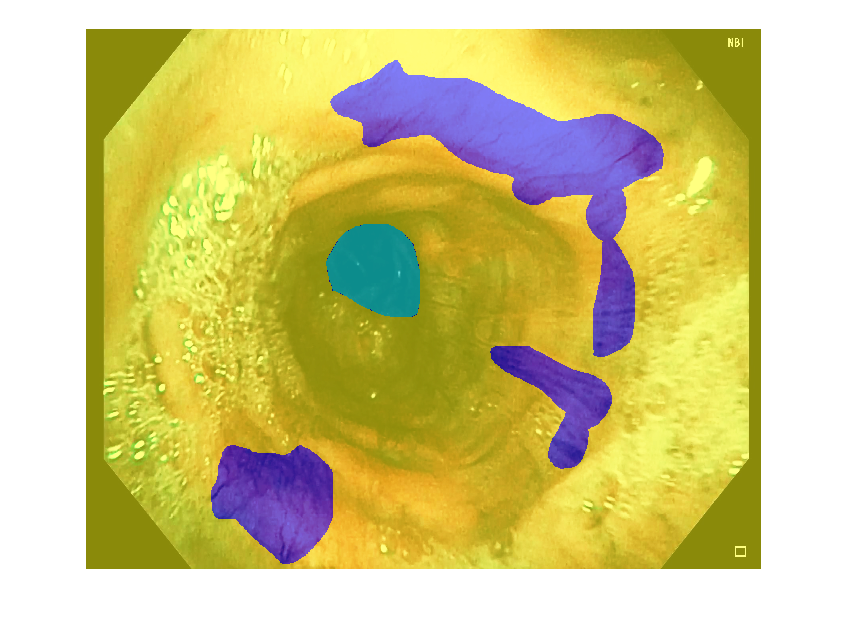

C = readimage(pxds,randNum);
B = labeloverlay(I,C);
imshow(B)

## Analyze Dataset Statistics

To see the distribution of class labels in the dataset, use `countEachLabel`. This function counts the number of pixels by class label.

tbl = countEachLabel(pxds)

tbl = 3×3 table
       Name       PixelCount    ImagePixelCount
    __________    __________    _______________

    'mucosa'      3.1521e+08      4.2865e+08   
    'vascular'     8.008e+07      4.2865e+08   
    'contrast'    3.3364e+07      4.2865e+08   


Visualize the pixel counts by class.

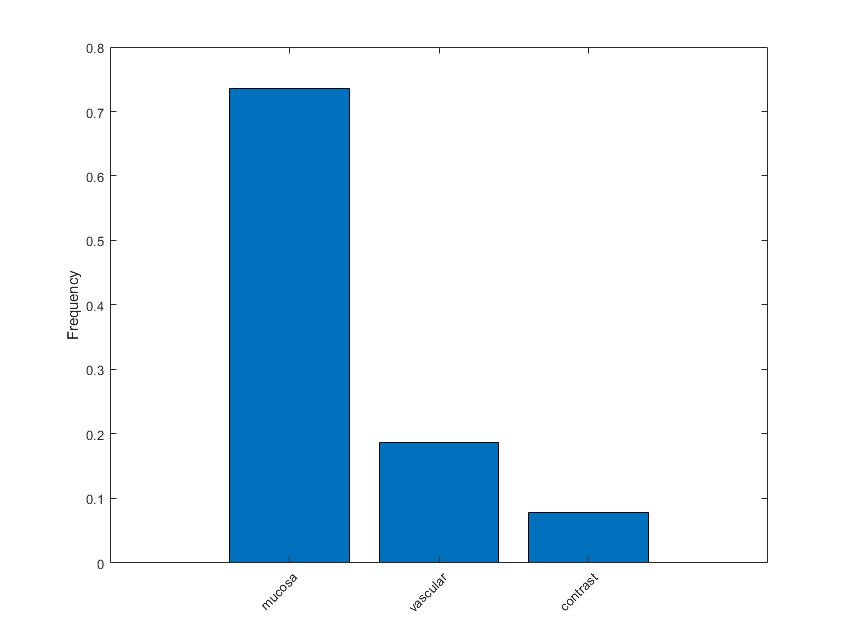

frequency = tbl.PixelCount/sum(tbl.PixelCount);

bar(1:numel(classes),frequency)
xticks(1:numel(classes)) 
xticklabels(tbl.Name)
xtickangle(45)
ylabel('Frequency')

Ideally, all classes would have an equal number of observations. However, the classes are imbalanced in our appplication, which is a common issue. If not handled correctly, this imbalance can be detrimental to the learning process because the learning is biased in favor of the dominant classes. Later on, we will use class weighting to handle this issue.

The frames driven from the NBI bronchoscopy procedure are 1080 by 1350 in size. Image size shoud be chosen such that a large enough batch of images can fit in memory during training on an NVIDIA GeForce RTX 2080 with 8 GB of memory. You may need to resize the images to smaller sizes if your GPU does not have sufficient memory or reduce the training batch size.

## Prepare Training, Validation, and Test Sets

Deeplab v3+ is trained using 70% of the images from the dataset. The rest of the images are split in 10% and 20% for validation and testing respectively. The following function randomly splits the image and pixel label data into a training, validation and test set.

% [imdsTrain, imdsTest, pxdsTrain, pxdsTest] = partitionData(imds,pxds,labelIDs);
[imdsTrain, imdsVal, imdsTest, pxdsTrain, pxdsVal, pxdsTest] = partitionData(imds,pxds,labelIDs);

The 70/10/20 split results in the following number of training, validation and test images:

numTrainingImages = numel(imdsTrain.Files)

numTrainingImages = 206

numValImages = numel(imdsVal.Files)

numValImages = 29

numTestingImages = numel(imdsTest.Files)

numTestingImages = 59

## Create the Network

Use the `helperDeeplabv3PlusResnet18` function, to create a DeepLab v3+ network based on ResNet-18.

% Specify the network image size.
imageSize = [1080 1350 3];

% Specify the number of classes.
numClasses = numel(classes);

% Create DeepLab v3+.
lgraph = helperDeeplabv3PlusResnet18(imageSize, numClasses);

## Balance Classes Using Class Weighting

As mentioned earlier, the classes in our dataset are not balanced. To improve training, we can use class weighting to balance the classes. We use the pixel label counts computed earlier with  `countEachLabel` and calculate the median frequency class weights.

imageFreq = tbl.PixelCount ./ tbl.ImagePixelCount;
classWeights = median(imageFreq) ./ imageFreq

classWeights =     0.2541
    1.0000
    2.4002


Specify the class weights using a  `pixelClassificationLayer`.

pxLayer = pixelClassificationLayer('Name','labels','Classes',tbl.Name,'ClassWeights',classWeights);
lgraph = replaceLayer(lgraph,"classification",pxLayer);

## Select Training Options

The optimization algorithm used for training is stochastic gradient descent with momentum (SGDM). Use `trainingOptions` to specify the hyper-parameters used for SGDM.

% Define validation data.
pximdsVal = pixelLabelImageDatastore(imdsVal,pxdsVal);

% Define training options. 
options = trainingOptions('sgdm', ...
    'LearnRateSchedule','piecewise',...
    'LearnRateDropPeriod',10,...
    'LearnRateDropFactor',0.3,...
    'Momentum',0.9, ...
    'InitialLearnRate',1e-3, ...
    'L2Regularization',0.005, ...
    'ValidationData',pximdsVal,...
    'MaxEpochs',30, ...  
    'MiniBatchSize',4, ...
    'Shuffle','every-epoch', ...
    'CheckpointPath', currentFolder, ...
    'VerboseFrequency',2,...
    'Plots','training-progress',...
    'ValidationPatience', 4); ...

The learning rate uses a piecewise schedule. The learning rate is reduced by a factor of 0.3 every 10 epochs. This allows the network to learn quickly with a higher initial learning rate, while being able to find a solution close to the local optimum once the learning rate drops.

The network is tested against the validation data every epoch by setting the `'ValidationData'` parameter. The `'ValidationPatience'` is set to 4 to stop training early when the validation accuracy converges. This prevents the network from overfitting on the training dataset.

A mini-batch size of 4 is used to reduce memory usage while training. You can increase or decrease this value based on the amount of GPU memory you have on your system.

In addition, `'CheckpointPath'` is set to a temporary location. This name-value pair enables the saving of network checkpoints at the end of every training epoch. If training is interrupted due to a system failure or power outage, you can resume training from the saved checkpoint.

## Data Augmentation

Data augmentation is used during training to provide more examples to the network because it helps improve the accuracy of the network. Here, random left/right reflection and random X/Y translation of +/- 10 pixels is used for data augmentation. We use the `imageDataAugmenter` to specify these data augmentation parameters.

augmenter = imageDataAugmenter('RandXReflection',true,...
    'RandXTranslation',[-10 10],'RandYTranslation',[-10 10]);

## Start Training

We combine the training data and data augmentation selections using `pixelLabelImageDatastore`. The `pixelLabelImageDatastore` reads batches of training data, applies data augmentation, and sends the augmented data to the training algorithm.

pximds = pixelLabelImageDatastore(imdsTrain,pxdsTrain, ...
    'DataAugmentation',augmenter);

Start training using `trainNetwork` if the `doTraining` flag is true. Otherwise, load a pretrained network.

Note: The training was verified on an NVIDIA GeForce RTX 2080 with 8 GB of GPU memory. If your GPU has less memory, you may run out of memory. If this happens, try setting `'MiniBatchSize'` to 1 in `trainingOptions`. Training this network takes about 5 hours. Depending on your GPU hardware, it can take even longer.

doTraining = true;
if doTraining    
    [DeepNet, info] = trainNetwork(pximds,lgraph,options);
else
    data = load(pretrainedNetwork); 
    DeepNet = data.net;
end

Training on single GPU.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|


|       1 |           1 |       00:00:28 |       29.93% |       28.98% |       1.2868 |       1.3022 |          0.0010 |
|       1 |           2 |       00:00:39 |       30.45% |              |       1.2771 |              |          0.0010 |
|       1 |           4 |       00:00:56 |       36.19% |              |       1.0293 |              |          0.0010 |
|       1 |           6 |       00:01:13 |       46.64% |              |       0.8591 |              |          0.0010 |
|       1 |           8 |       00:01:30 |       44.50% |              |       0.8422 |              |          0.0010 |
|       1 |          10 |       00:01:47 |       61.34% |              |       0.5708 |              |          0.0010 |
|       1 |          12 |       00:02:04 |       46.75% |              |       0.9437 |              |          0.0010 |
|       1 |          14 |       00:02:21 |       62.67% |              |       0.6047 |              |          0.0010 |
|       1 |          16 |       

|======================================================================================================================|


## Test Network on One Image

As a quick sanity check, run the trained network on one test image. 

randNumTesting = randi(numTestingImages);
I = readimage(imdsTest,randNumTesting);
C = semanticseg(I, DeepNet);

Display the results.

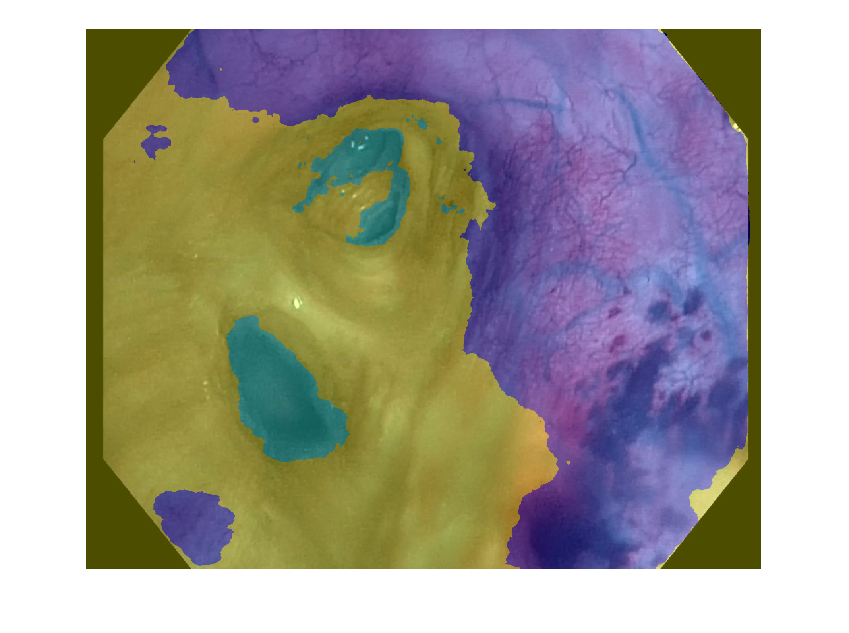

B = labeloverlay(I,C,'Transparency',0.7);
imshow(B)

Compare the results in `C` with the expected ground truth stored in `pxdsTest`. The green and magenta regions highlight areas where the segmentation results differ from the expected ground truth.

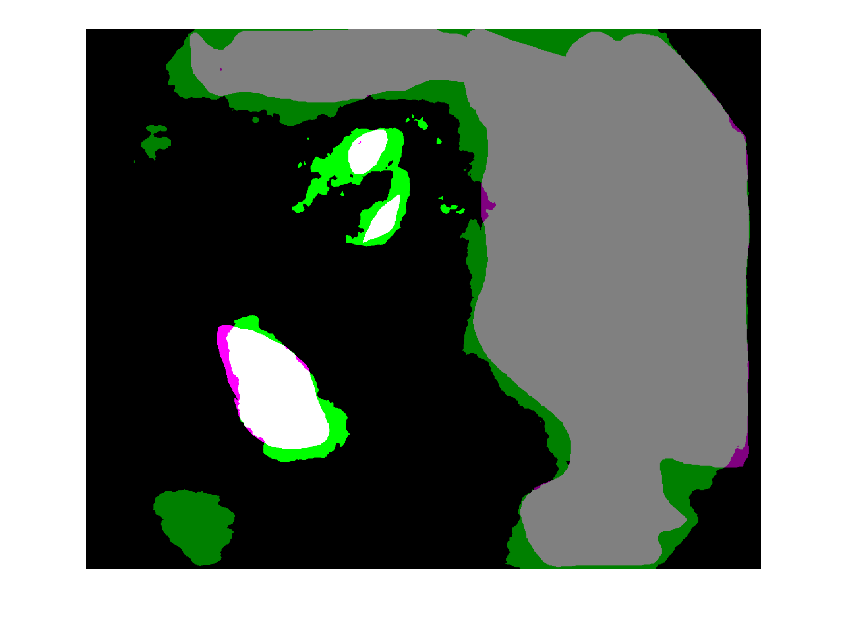

expectedResult = readimage(pxdsTest,randNumTesting);
actual = uint8(C);
expected = uint8(expectedResult);
imshowpair(actual, expected)

Visually, the semantic segmentation results overlap well for the vascular class. The amount of overlap per class can be measured using the intersection-over-union (IoU) metric, also known as the Jaccard index. We use the  `jaccard` function to measure IoU.

iou = jaccard(C,expectedResult);
table(classes,iou)

ans = 3×2 table
     classes        iou  
    __________    _______

    "mucosa"      0.86169
    "vascular"    0.85102
    "contrast"    0.57839


The IoU metric confirms the visual results.

## Evaluate Trained Network

To measure accuracy for multiple test images, we run `semanticseg` on the entire test set. A mini-batch size of 4 is used to reduce memory usage while segmenting images. You can increase or decrease this value based on the amount of GPU memory you have on your system. 

predictFolder = [currentFolder,'\predictions_157and168'];

imds.ReadFcn = @customReadDatastoreImage;

pxdsResults = semanticseg(imdsTest,DeepNet, ...
    'MiniBatchSize',4, ...
    'WriteLocation',predictFolder,...
    'Verbose',true);

Running semantic segmentation network
-------------------------------------
* Processing 59 images.
* Progress: 100.00%



`semanticseg` returns the results for the test set as a `pixelLabelDatastore` object. The actual pixel label data for each test image in `imdsTest` is written to disk in the location specified by the `'WriteLocation'` parameter. We use  `evaluateSemanticSegmentation` to measure semantic segmentation metrics on the test set results. 

metrics = evaluateSemanticSegmentation(pxdsResults,pxdsTest,'Verbose',true);

Evaluating semantic segmentation results
---------------------------------[==================================================] 100%
Elapsed time: 00:00:21
Estimated time remaining: 00:00:00
* Finalizing... Done.
* Data set metrics:

    GlobalAccuracy    MeanAccuracy    MeanIoU    WeightedIoU    MeanBFScore
    ______________    ____________    _______    ___________    ___________

       0.91641          0.93563       0.79066      0.85229        0.50727  



`evaluateSemanticSegmentation` returns various metrics for the entire dataset, for individual classes, and for each test image. To see the dataset level metrics, inspect `metrics.DataSetMetrics` .

metrics.DataSetMetrics

ans = 1×5 table
    GlobalAccuracy    MeanAccuracy    MeanIoU    WeightedIoU    MeanBFScore
    ______________    ____________    _______    ___________    ___________

       0.91641          0.93563       0.79066      0.85229        0.50727  


The dataset metrics provide a high-level overview of the network performance. To see the impact each class has on the overall performance, inspect the per-class metrics using `metrics.ClassMetrics`.

metrics.ClassMetrics

ans = 3×3 table
                Accuracy      IoU      MeanBFScore
                ________    _______    ___________

    mucosa      0.90851     0.89046      0.68212  
    vascular     0.9224     0.73749      0.37295  
    contrast    0.97597     0.74404      0.46675  
